clc
clear all

ts = vector_tiempo(0.001, 0, 10); 
%Parametros de A: 
disp('Parmateros de A:  k1 = 1, m1 = 5')

Parmateros de A:  k1 = 1, m1 = 5


k1 = 1; m1 = 5; 
%disp('Intervalo de la grafica = [2.5, 8]')

%Paramtetros de B:
disp('Parametros de B: k1 = 1, m1 = 5')

Parametros de B: k1 = 1, m1 = 5


k2 = 1; m2 = 5; 
%disp('Intervalo de la grafica: [2.5, 10]')

%Paramtetros de A':
disp('Parametros de B: k1 = 3, m1 = 5')

Parametros de B: k1 = 3, m1 = 5


k3 = 2; m3 = 5; 
%disp('Intervalo de la grafica: [2.5, 10]')

l 

%%


% Generacion de la grafica A: 
for j = 1:cols
    a_gaussiana(:,j) = exp(-k1*(ts(:,j)-m1)^2);
end

%Generacion de la grafica B: 
for j = 1:cols
    b_pseudo(:,j) = 1/(1+k2*(d - m2)^2);
end


%Generacion de la grafica A': 
for j = 1:cols
    a_dif_pseudo(:,j) = 1/(1+k3*(ts(:,j) - m3)^2);
end
disp('a')

a



%% R(x,y)
fun_r = zeros(rows, cols); 
y = zeros(cols, cols); 

%Donde i es el recorrido por A y j por B
for i = 1:cols
    for j = 1:cols
        fun_r(:,j) = min(1, 1 - a_gaussiana(:,i) + b_pseudo(:,j));
        y(i,j) = fun_r(:,j);
    end 
end
disp('a')

a


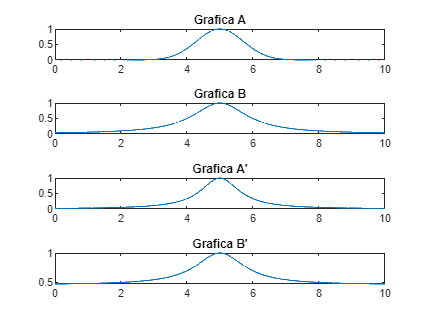


%% Bprima: 
b_min = zeros(cols, cols); 
for i = 1:cols
    for j = 1:cols
        b_min(i, j) = min(a_dif_pseudo(:,j), y(j,i)) ;
    end
end


for j = 1:cols
    b_dif_pseudo(:,j) = max( b_min(j,:));
end


%% Display graficas: 
%
tiledlayout(4,1)
nexttile
plot(ts, a_gaussiana)
title("Grafica A")

nexttile
plot(ts, b_pseudo)
title("Grafica B")

nexttile
plot(ts, a_dif_pseudo)
title("Grafica A'")

nexttile
plot(ts, b_dif_pseudo)
title("Grafica B'")